Outage Script

                      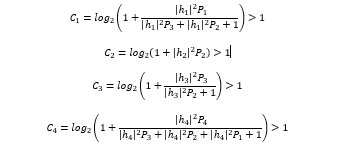        

trials=1000;
scale=1;
power_total=[800,895,1000,1222,1268,1452,1584,1778,2000,2238,2511,2888,3169,410];%[800,895,100,122,126,145,158,177,200,223,251,288,316,410];
power_total=sort(power_total./scale);
prob_outage=zeros(length(power_total),4);
for i=1:length(power_total)
    p=zeros(1,4);
    no_outages=zeros(1,4);
    for j=1:trials
        h = [abs(1*randn()),abs(2*randn()),abs(3*randn()),abs(4*randn()),power_total(i)];
        p=noma_neural(h);
        
        c1 = log2(1+((h(1)^2)*p(1)/((h(1)^2)*p(2)+(h(1)^2)*p(3)+1)));
        c2 = log2(1+(h(2)^2)*p(2));
        c3 = log2(1+((h(3)^2)*p(3)/((h(2)^2)*p(2)+1)));
        c4 = log2(1+((h(4)^2)*p(4)/((h(4)^2)*p(1)+(h(4)^2)*p(2)+(h(4)^2)*p(3)+1)));
        
        if(c1>1)
            no_outages(1)=no_outages(1)+1;    
        end
        if(c2>1)
            no_outages(2)=no_outages(2)+1;    
        end
        if(c3>1)
            no_outages(3)=no_outages(3)+1;    
        end
        if(c4>1)
            no_outages(4)=no_outages(4)+1;    
        end    
    end

    prob_outage(i,:)=no_outages./trials;
    
end

Plotting assistance

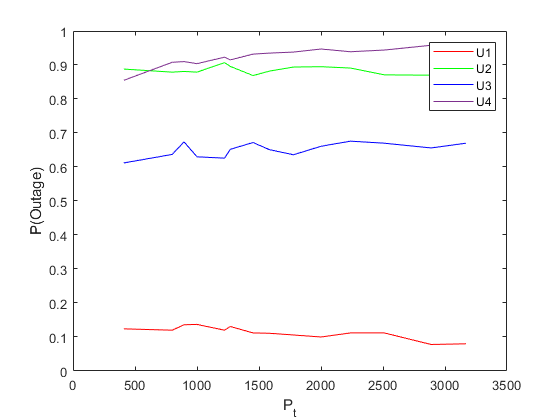


plot(power_total,prob_outage(:,1),"r");
xlabel("P_total")
ylabel("P(Outage)")
ylim([0,1]);
hold on

plot(power_total,prob_outage(:,2),"g");
xlabel("P_total");
ylabel("P(Outage)")
ylim([0,1]);
hold on ;


plot(power_total,prob_outage(:,3),"b");
xlabel("P_total");
ylabel("P(Outage)")
ylim([0,1]);
hold on;


plot(power_total,prob_outage(:,4));
xlabel("P_t");
ylabel("P(Outage)")
legend("U1","U2","U3","U4")
ylim([0,1]);
hold on